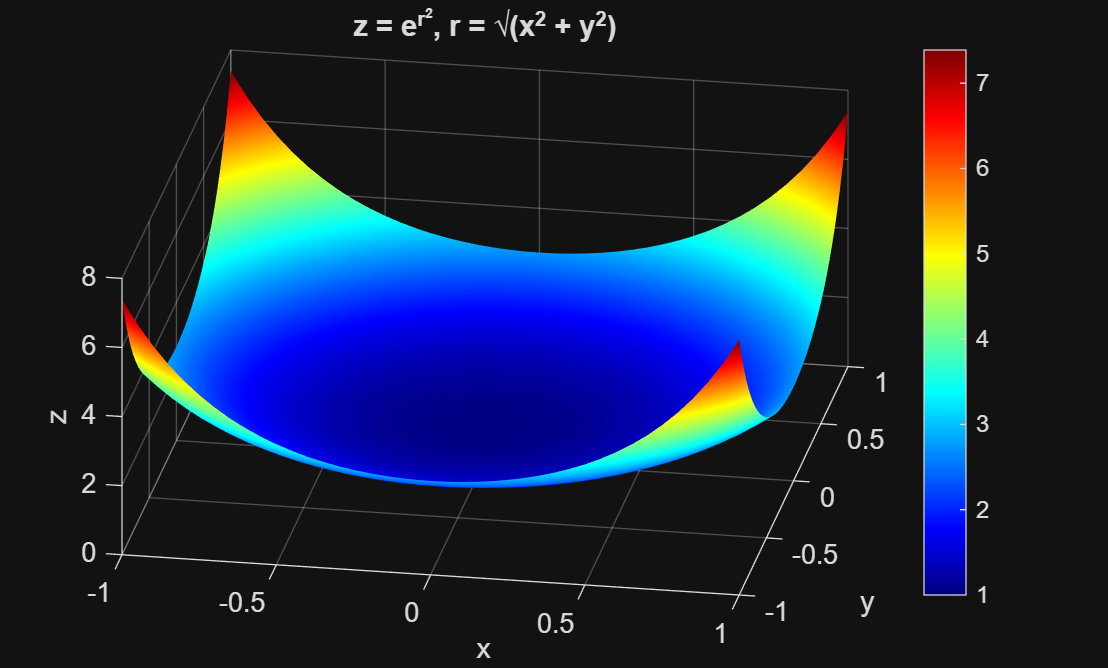

clear all
%LD4 Vladislav Romov

% 1)Trimatis grafiku vaizdavimas
%A)
[x, y] = meshgrid(-1:0.05:1, -1:0.05:1);
r = sqrt(x.^2 + y.^2);
z = exp(r.^2);
surf(x, y, z)
colormap(jet) 
colorbar
shading interp  
view(10, 40) 
xlabel('x'); ylabel('y'); zlabel('z');
title('z = e^{r^2}, r = \surd(x^2 + y^2)');

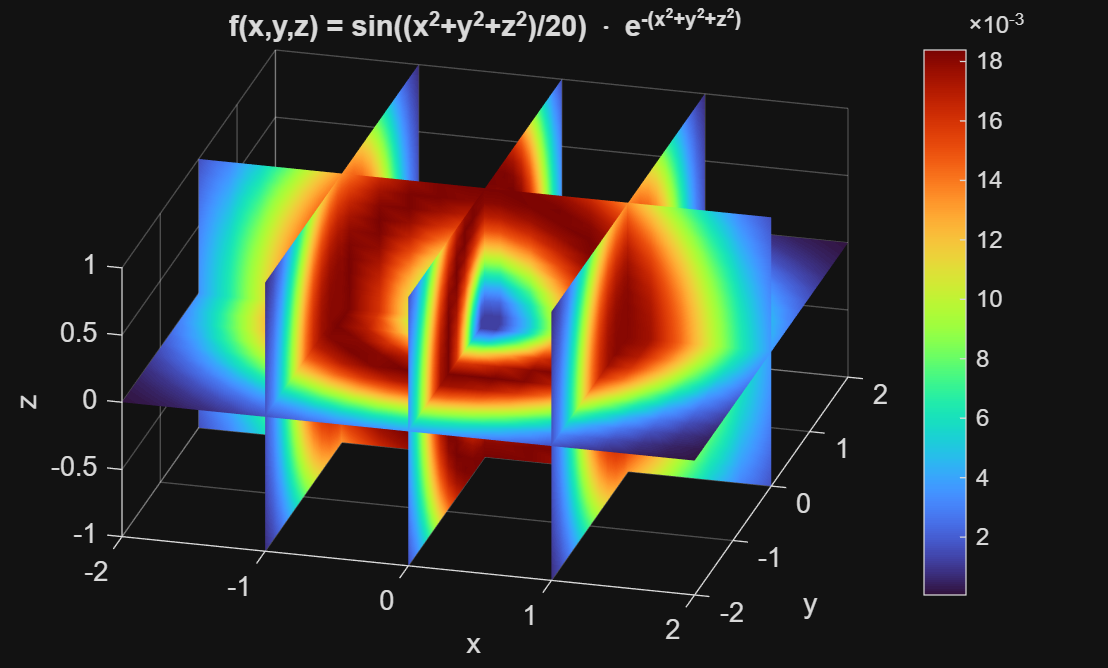

%B)
A=linspace(-2, 2, 20);
B=linspace(-2, 2, 20);
C=linspace(-1, 1, 20);
[x, y, z]=meshgrid(A, B,C);
f=sin((x.^2 + y.^2 + z.^2) / 20) .* exp(-(x.^2 + y.^2 + z.^2));
slice(x, y, z, f, [-1 0 1], [0], [0])   
colormap(turbo)                           
colorbar                                
shading interp
view(15, 40)                            
xlabel('x'); ylabel('y'); zlabel('z');
title('f(x,y,z) = sin((x^2+y^2+z^2)/20) \cdot e^{-(x^2+y^2+z^2)}');

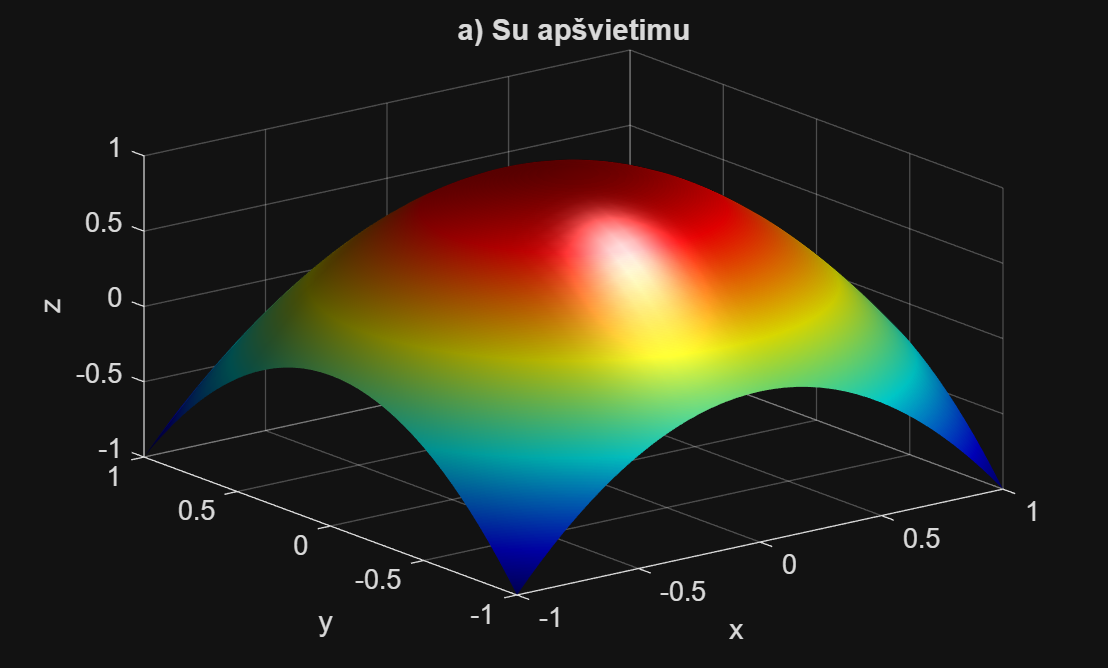

%Papildoma uzduotis:
[x, y] = meshgrid(-1:0.05:1, -1:0.05:1);
z = 1 - (x.^2 + y.^2);

% a)SU apsvetimu
figure(1)
surf(x, y, z)
shading interp
colormap(jet)    
camlight
lighting gouraud
title('a) Su apšvietimu')
xlabel('x'); ylabel('y'); zlabel('z');

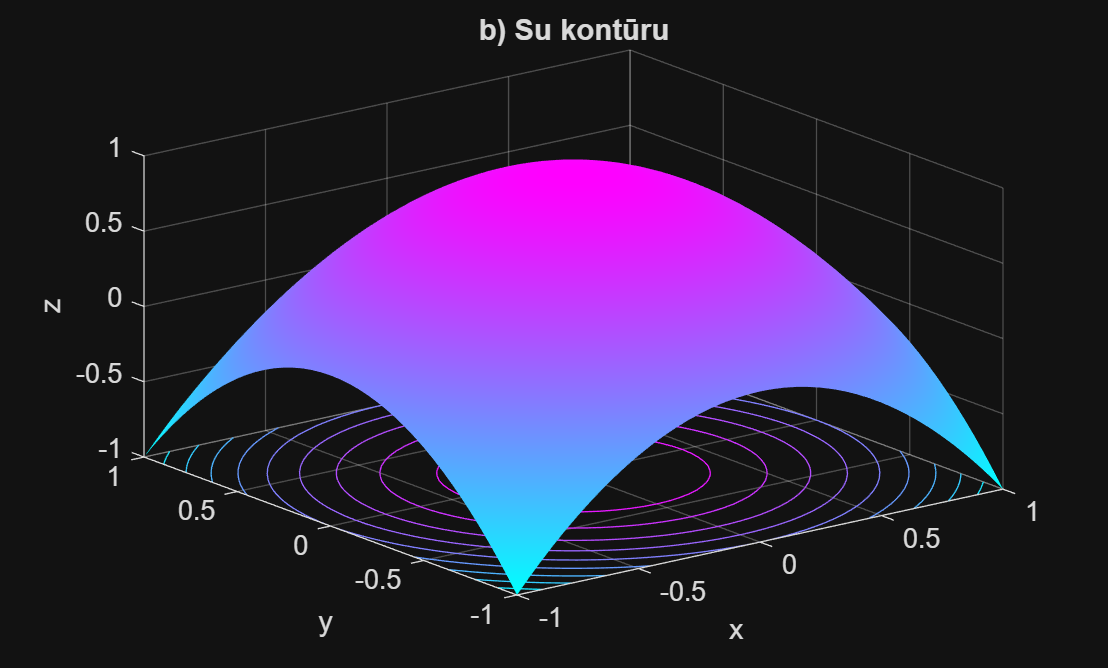


% b)Su kontūru 
figure(2)
surfc(x, y, z)
shading interp
colormap(cool)    
title('b) Su kontūru')
xlabel('x'); ylabel('y'); zlabel('z');

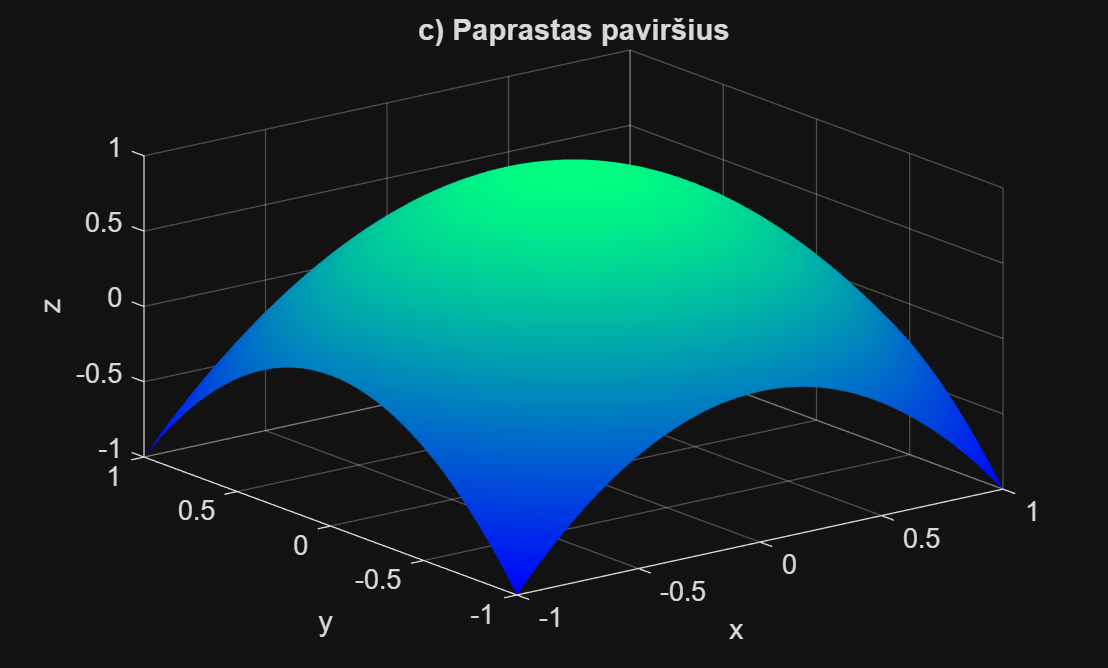


% c)Paprastas paviršius
figure(3)
surf(x, y, z)
shading interp
colormap(winter)    
title('c) Paprastas paviršius')
xlabel('x'); ylabel('y'); zlabel('z');